arcpoints = load ('hockeyarcpoints.txt','-ascii');
[arcpointsizex,~] = size(arcpoints);
sizex = max(arcpoints(:,2));
sizey = max(arcpoints(:,3));
arc = 0;
new_label = 0;

cellArc = {};
for i = 1 : arcpointsizex
    arc_label = arcpoints(i,1);
    if arc~=arc_label
        if arc > 0
            cellArc{new_label} = H;
        end
        arc = arc_label;
        new_label = new_label+1;
        H = [];
        k = 1;
    end
    H(k,1) = arcpoints(i,2)+1;
    H(k,2) = arcpoints(i,3)+1;
    H(k,3) = arcpoints(i,1);
    k = k + 1;
end
% Successfully saved arcs to cellArc
% coordinate +1, +1

[~, arc_num] = size(cellArc);
thinArc = cell(arc_num,1);
sol = zeros(5,arc_num);
for i = 1 : arc_num
    [point_num,~] = size(cellArc{i});
    img = full(sparse(cellArc{i}(:,1),cellArc{i}(:,2),ones(point_num,1)));
    [thinArc{i}(:,1),thinArc{i}(:,2), ~ ] = find(bwskel(logical(img)));
    [thin_num,~] = size(thinArc{i});
    F = zeros(point_num,5);
    G = zeros(point_num,1);
    for j = 1 : thin_num
        F(j,1) = thinArc{i}(j,1) * thinArc{i}(j,2) / (sizex * sizey);
        F(j,2) = thinArc{i}(j,2)^2 / (sizey ^ 2);
        F(j,3) = thinArc{i}(j,1) / (sizex);
        F(j,4) = thinArc{i}(j,2) / sizey;
        F(j,5) = 1;
        G(j) = thinArc{i}(j,1)^2 / sizex^2;
    end
    sol(:,i) = F\G;
end

% thin Arc Done
% sol done
% F,G is transformed 1/sizex, 1/sizey

  490.0544



     2



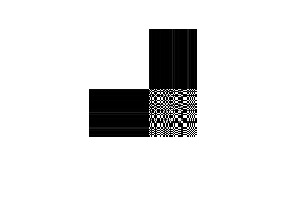

   68.2813



     3



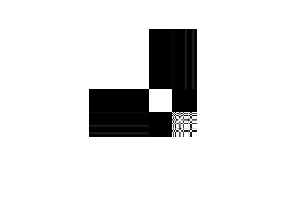

    8.0211



     4



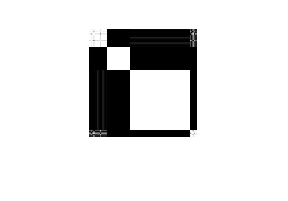

    6.5318



     5



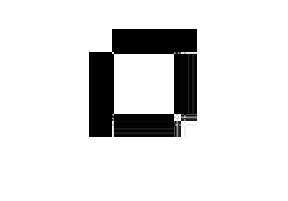

    5.4672



     6



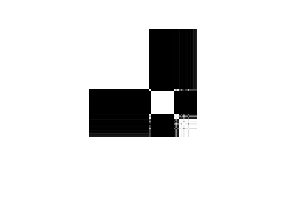

    3.3023



     7



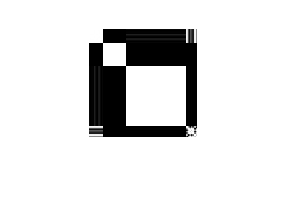

    2.3183



     8



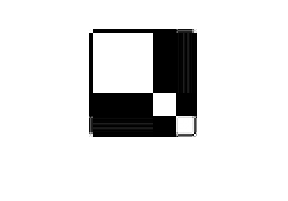

    1.6054



     9



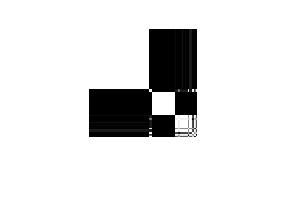

    1.6671



    10



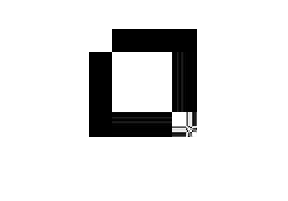

output = sol(:,sol(1,:).^2-4.*sol(2,:)<0);
[~,out_num] = size(output);
cor = zeros(out_num);
for i = 1 : out_num
    for j = 1 : out_num
        cor(i,j) = Distance(output(:,i),output(:,j));
    end
end
[u,~,~]=svd(cor);
Sam = cor*u(:,1:5);
sums = zeros(1,10);
C = cell(10,1);
id = cell(10,1);
for j = 2:10 % kmeans 的 k
[ind,M,sumd] = kmeans(Sam,j);
[~,I]=sort(ind);
newcor = cor(I,I);
img=mat2gray(newcor);%将数值矩阵X转换为灰度图像
C(j)={M};
id(j)={ind};
sums(j) = sum(sumd);
disp(sums(j))
disp(j)
figure,imshow(img);
end

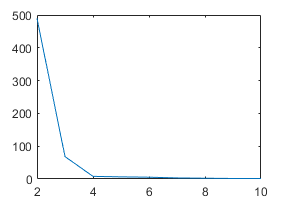

sums(1) = NaN; % 去掉 k = 1 无意义
plot(sums) % 误差图 k = 3

k = 4;
group = id{k};
cocl = zeros(out_num,k);
for i = 1 : k
    [y,z] = find(group == i);
    f = full(sparse(y,z,1));
    [x,~] = size(f);
    cocl(1:x,i) = f;
end
conum = zeros(1,k);
for i = 1 : k
    conum(i) = sum(cocl(:,i));
end
% construct group matrix
% k columns in matrix cocl, each column tells us which arc belongs to
% which ellipse

output * cocl

ans =     1.9825   -0.0000         0   -2.8387
    1.2040    0.0000    0.0000   94.1209
    7.0611   59.5290         0   12.7366
   -1.2773   -0.0000   -0.0000  -74.6566
   -2.2877  -22.0027    5.5749   16.6352


cocl

cocl =      0     1     0     0
     0     0     0     1
     0     0     1     0
     0     1     0     0
     0     1     0     0
     0     1     0     0
     1     0     0     0
     0     1     0     0
     0     1     0     0
     0     1     0     0


conum

conum =      7    60    23    18


s = [];
for i = 1 : arc_num
    s = [s;thinArc{i}];
end
% gather all thin arc points

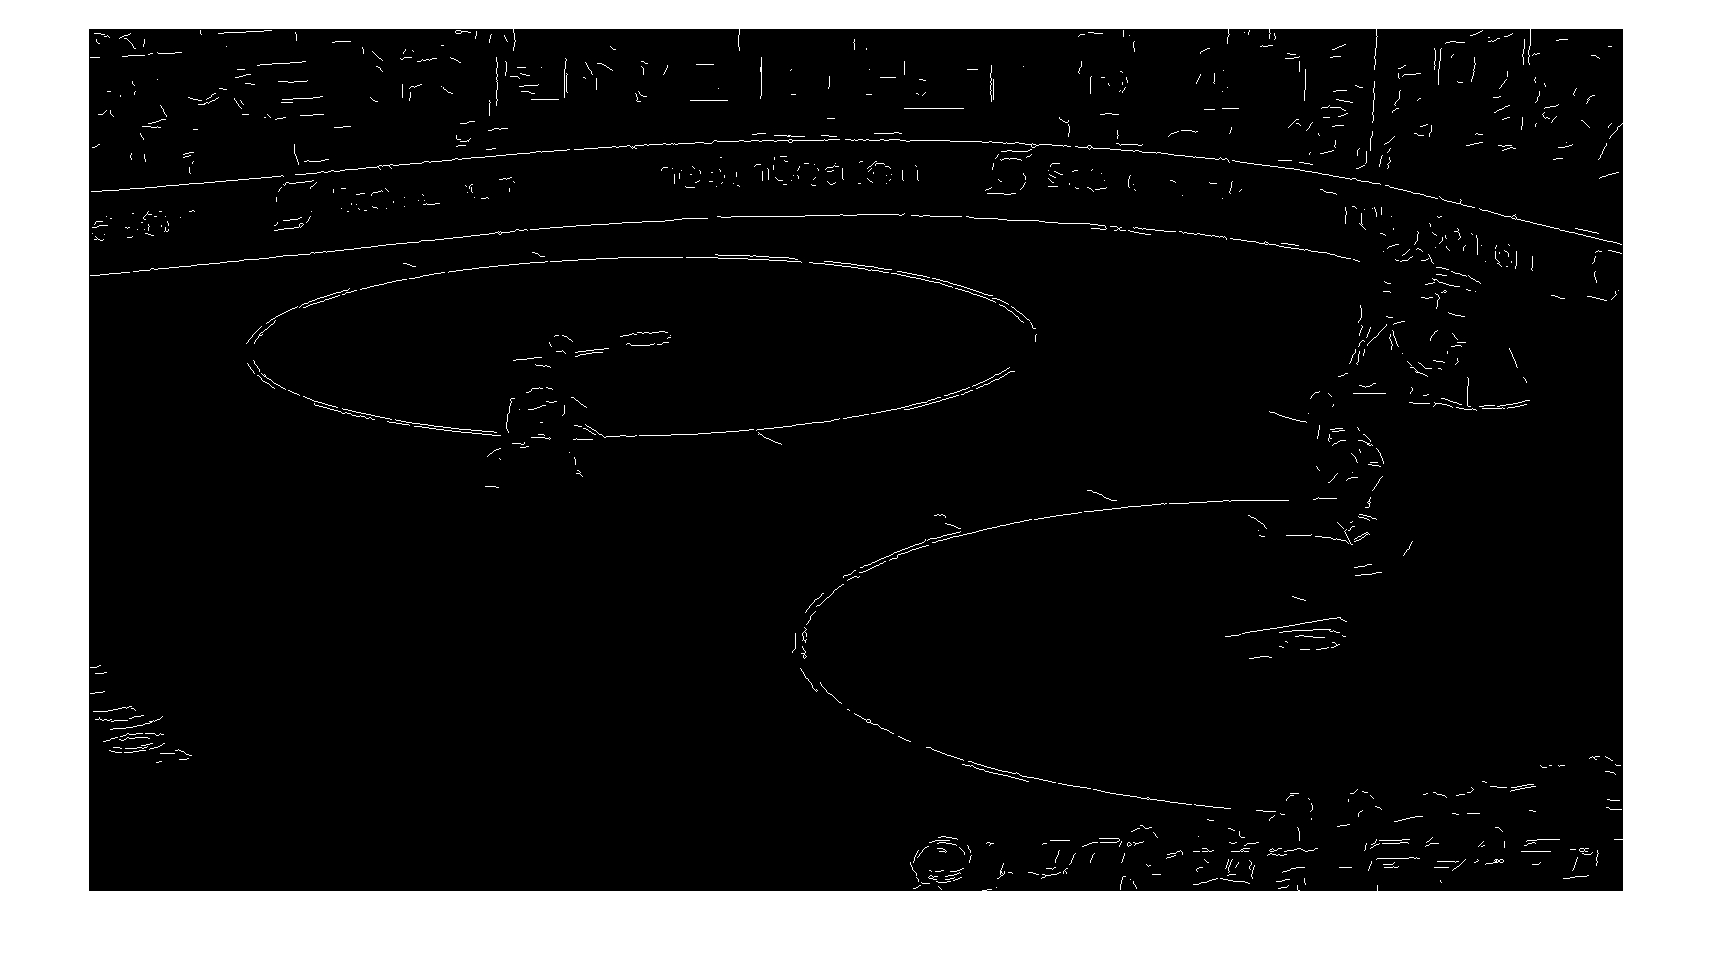

S = sparse(s(:,1),s(:,2),1);
imshow(full(S))